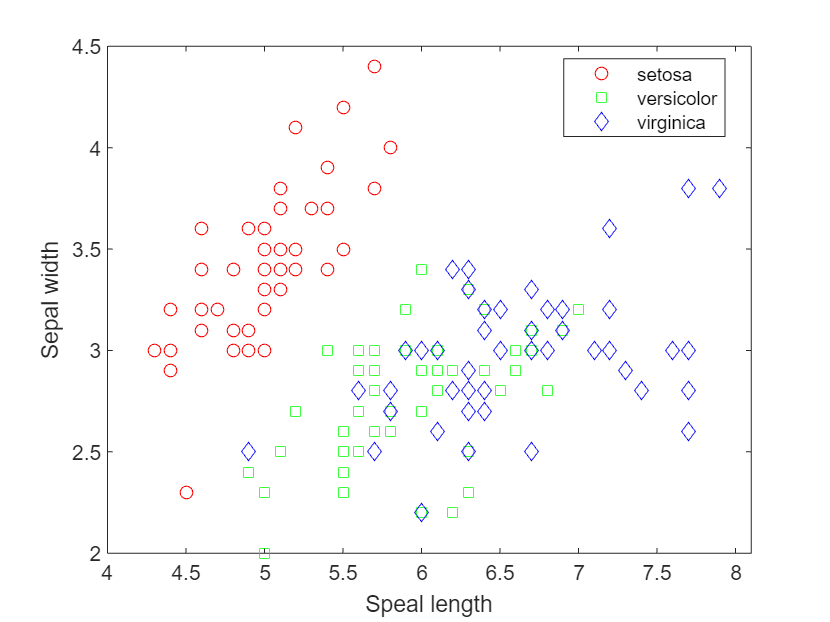

%Visualize the data simply using the first two measures of the samples
load fisheriris.mat
gscatter(meas(:,1),meas(:,2),species,'rgb','osd');
xlabel('Speal length');
ylabel('Sepal width');

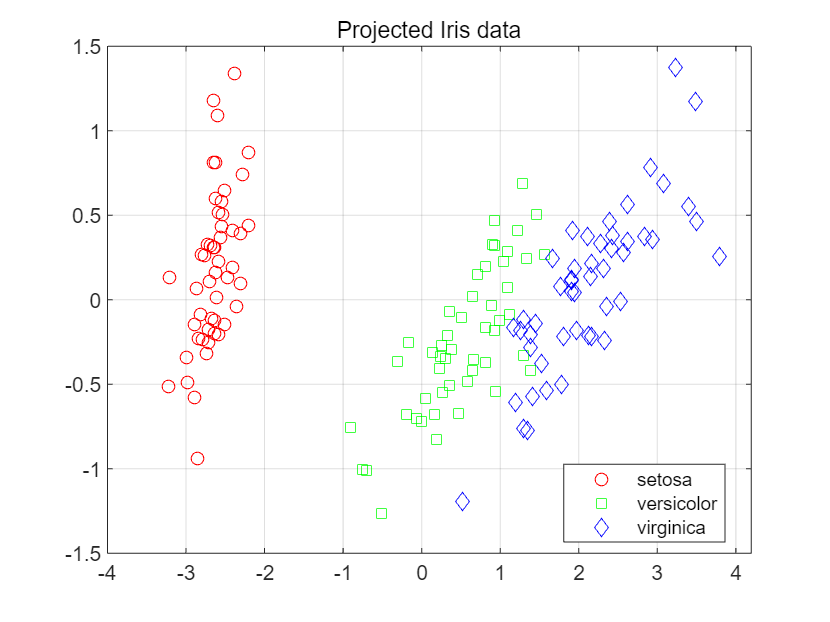


%visualizing the data using PCA
m=mean(meas);
meas=meas-repmat(m,size(meas,1),1);
covar=cov(meas);
[v,d]=eigs(covar);

score=meas*v(:,1:2);%%get the projection scores on the first two leading vectos

figure(2)
gscatter(score(:,1),score(:,2),species,'rgb','osd')
title('Projected Iris data'),grid on

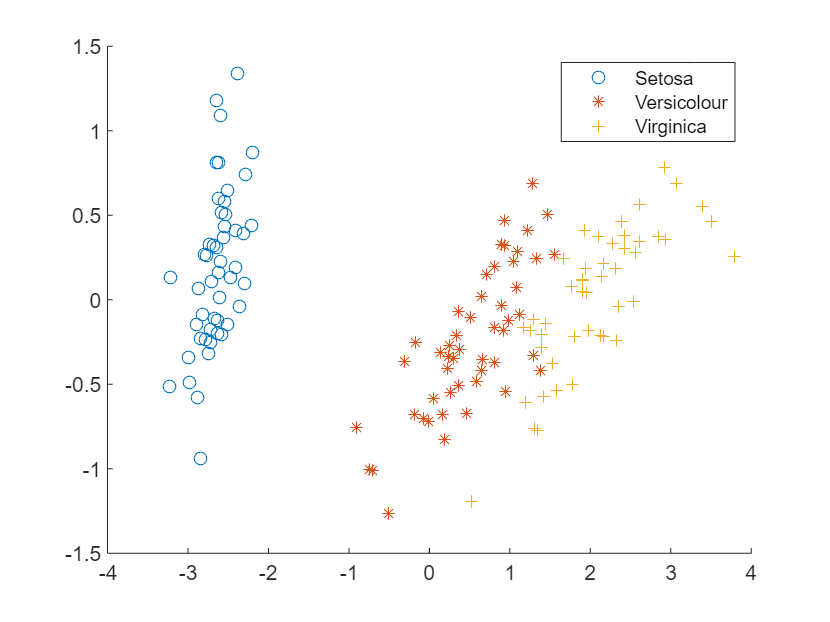


figure(3)
hold on;
plot(score(1:50,1),score(1:50,2),'o');
plot(score(51:100,1),score(51:100,2),'*');
plot(score(101:150,1),score(101:150,2),'+');
hold off;
legend('Setosa','Versicolour','Virginica');

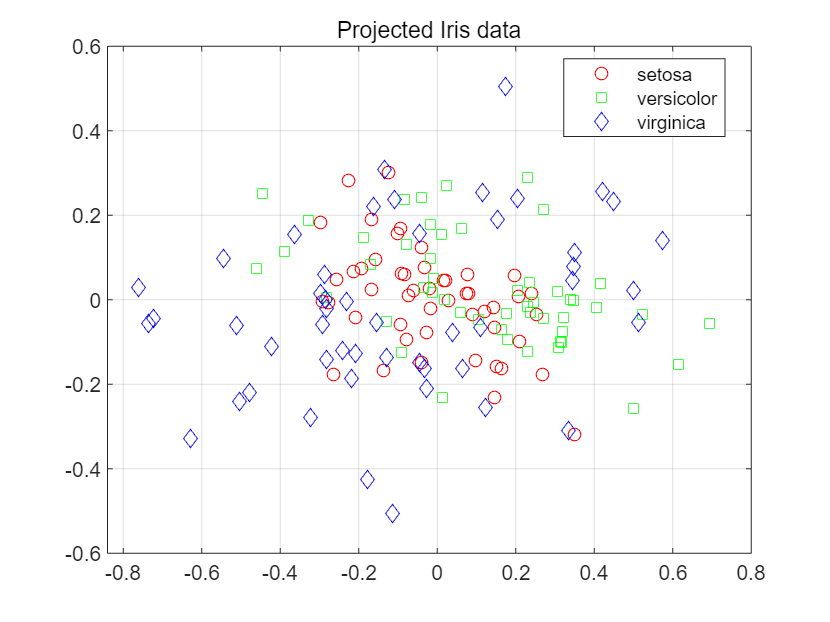


% using the last two leading vectors
score2=meas*v(:,3:4);%%get the projection scores on the first two leading vectos

figure(4)
gscatter(score2(:,1),score2(:,2),species,'rgb','osd')
title('Projected Iris data'),grid on


% figure(6)
% hold on;
% plot(score2(1:50,1),score2(1:50,2),'o');
% plot(score2(51:100,1),score2(51:100,2),'*');
% plot(score2(101:150,1),score2(101:150,2),'+');
% hold off;
% legend('Setosa','Versicolour','Virginica');